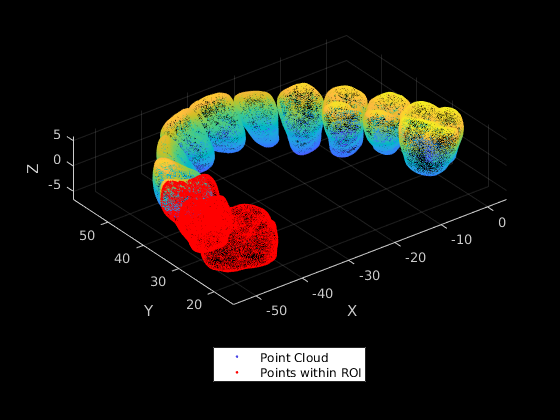

clear;
clc;

stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);

%Select three teeth
roi = [-60 -40 10 40 -6 6];
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);

%Plot full point cloud
figure
pcshow(ptCloud)
hold on
%Plot selected portion
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off

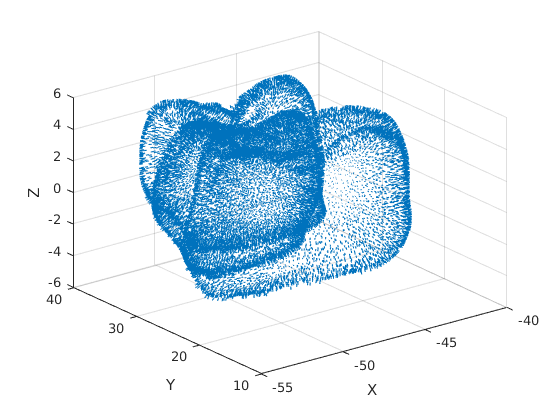


%Calculate Normals
normals = pcnormals(ptCloudB);
x = ptCloudB.Location(:,1);
y = ptCloudB.Location(:,2);
z = ptCloudB.Location(:,3);
u = normals(:,1);
v = normals(:,2);
w = normals(:,3);

%Plot normals
figure
quiver3(x,y,z,u,v,w);
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off

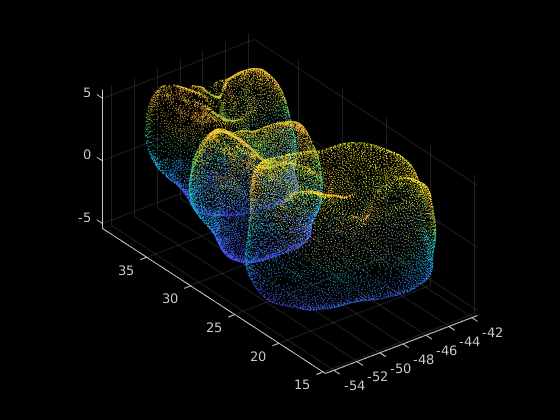


%Transformation (shrink)
Sx = 0.75;
Sy = 0.75;
Sz = 0.75;
tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloudC = pctransform(ptCloudB,tform);
figure
pcshow(ptCloudB)
hold on

% pcshow(ptCloudC)

% Assume a plane in z and plot x,y for that plane. This is how we can plot 
% x's and y's for other z planes assuming we go up and down in the z direction.

k = 1;

for i = 1:length(ptCloudB.Location(:,3))
    j = ptCloudB.Location(i,3);
    if j < 0.3 && j > -0.3
        a(k,1) = ptCloudB.Location(i,1);
        b(k,1) = ptCloudB.Location(i,2);
        k = k+1;
    end
end
mat = [a,b]

mat =   -51.2459   39.3609
  -51.2024   39.4970
  -51.1845   39.4625
  -51.0625   39.7923
  -51.3148   37.7138
  -51.3312   37.7159
  -51.2981   37.5801
  -51.2447   37.4020
  -51.1870   37.2515
  -48.0360   33.9094


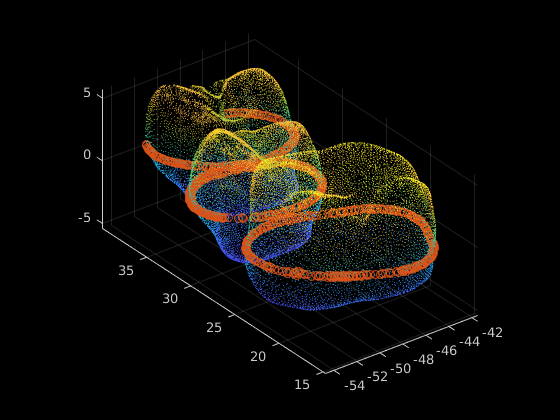

scatter(a,b)

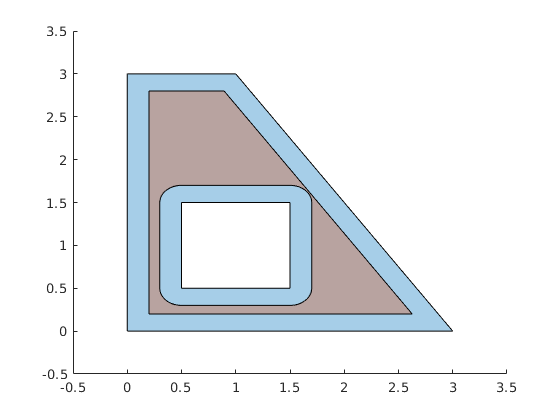

polyin = polyshape({[0 0 1 3],[0.5 1.5 1.5 0.5]},{[0 3 3 0],[0.5 0.5 1.5 1.5]});
plot(polyin)
polyout1 = polybuffer(polyin,-0.2);
hold on
plot(polyout1)
hold off

figure
polyin = polyshape({a},{b});

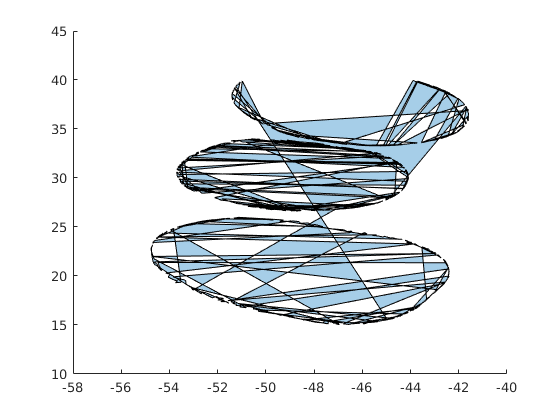

plot(polyin)
polyout1 = polybuffer(polyin,-0.2);
hold on

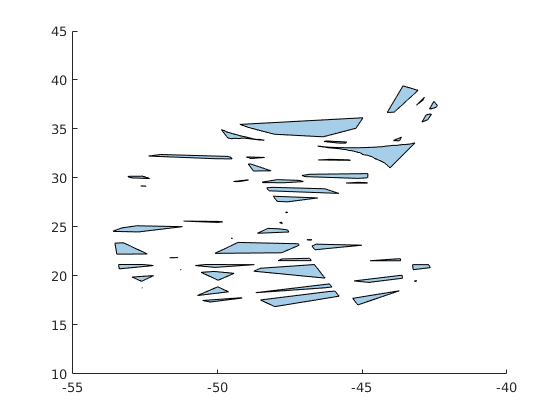

figure
plot(polyout1)
hold off